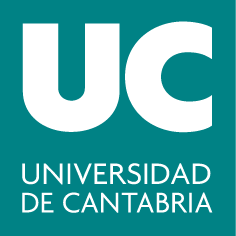

#### ***Grado en Ingeniería Química***

## **G320: Álgebra**

# **Práctica 7: Espacios vectoriales (II)**

*Rodrigo García Manzanas (rodrigo.manzanas@unican.es)*

*Valvanuz Fernández Quiruelas (valvanuz.fernandez@unican.es)*

**Objetivos**

- Calcular la suma e intersección de subespacios

- Comprobar si dos subespacios están o no en suma directa

- Obtener subespacios complementarios

**Intersección de subespacios**

Sean $S$ y $T$ dos subespacios de $\mathbb{R}^4$ dados por sus ecuaciones implícitas:

                                                      
$$S: \left.
x + y - z - t = 0 \atop
2x + 2y - z - t = 0
\right\} $$
                           
$$T: \left.
x - y = 0 \atop
z - t = 0
\right\} $$


El subespacio $S \cap T$ se calcula resolviendo el sistema formado por las ecuaciones de $S$ y las de $T$, ya que cualquier elemento de la intersección estará a la vez en $S$ y en $T$, y por tanto, verificará ambos conjuntos de ecuaciones simultáneamente.  

coefImpS = [1 1 -1 -1; 2 2 -1 -1]  % coefs. eqs. implícitas S
coefImpT = [1 -1 0 0; 0 0 1 -1]  % coefs. eqs. implícitas T
baseSinterT = null([coefImpS; coefImpT], 'r')  % resuelvo el sistema homogéneo --> 
% sólo tiene la solución trivial, por lo que el subespacio intersección 
% está compuesto tan sólo por el vector 0 --> S y T están en suma directa

**Suma de subespacios**

Para calcular el subespacio $S+T$, obtendremos en primer lugar una base de $S$ y otra de $T$. A partir de ellas, es inmediato formar un sistema generador de $S+T$ (sólo habrá que unir ambas bases). Finalmente, para obtener una base de $S+T$, sólo nos quedará identificar los vectores del sistema generador que sean linealmente independientes. Si hubiera algún vector linealmente dependiente de los demás, habría que eliminarlo. 

baseS = null(coefImpS, 'r')  % base de S --> dim(S)=2
baseT = null(coefImpT, 'r')  % base de T --> dim(T)=2
genST = [baseS baseT]  % sistema generador de S+T
rank(genST)  % rango máximo --> sistema libre 
% Por tanto, genST será una base del subespacio suma (S+T), es decir:
baseST = genST  % dim(S+T)=4
% Al haber 4 vectores en esta base, esto quiere decir que S+T será
% todo R4 --> S y T son subespacios complementarios, puesto que 
% dim(S)+dim(T) = dim(S+T) y S+T=R4

#### **Búsqueda de subespacios complementarios**

Sea el subespacio $S: \lbrace (x,y,z,t,p): -143x -54y -44p = 0, t = 0
\rbrace $ de $\mathbb{R}^5$. Para encontrar un subespacio complementario (o suplementario) de $S$ comenzaremos por obtener una base de $S$:

coefImpS = [-143 -54 0 0 -44; 0 0 0 1 0]
baseS = null(coefImpS, 'r')  % dim(S)=3
rank(baseS)

A partir de aquí, se trata de extender esta base añadiendo nuevos vectores que sean linealmente independientes de los anteriores hasta formar una base del espacio total, $\mathbb{R}^5$ en este caso. Para ello podemos elegir cualquier vector, por ejemplo, los de la base canónica de $\mathbb{R}^5$.

rank([baseS, [1 0 0 0 0]'])  % ya tenemos el primer vector de la base del complementario: (1,0,0,0,0)
rank([baseS, [1 0 0 0 0]', [0 1 0 0 0]'])  % el vector (0,1,0,0,0) no nos sirve, ya que no es L.I. de los demás
rank([baseS, [1 0 0 0 0]', [0 0 1 0 0]'])  % el vector (0,0,1,0,0) no nos sirve, ya que no es L.I. de los demás
rank([baseS, [1 0 0 0 0]', [0 0 0 1 0]'])  % ya tenemos el segundo vector que necesitábamos para la base del complementario: (0,0,0,1,0)

Los vectores que hemos añadido a los de la base de $S$ forman una base del complementario que buscábamos: $\lbrace (1,0,0,0,0), (0,0,0,1,0)\rbrace$

***Nota*****: **Recuerda que dados dos subespacios $S$ y $T$ cualesquiera siempre se cumplirá la fórmula de Grassmann: $\textbf{dim(S+T)=dim(S)+dim(T)-dim(S $\cap$ T)}$

#### Ejercicios propuestos

**Ejercicio 1:**

En $\mathbb{R}^4$, dados los subespacios $S : \lbrace (x, y, z, t): x=z, y = t\rbrace$ y $T : \lbrace (\alpha, 0, \alpha, \beta): \alpha, \beta \in \mathbb{R}\rbrace$, se pide:

- *a)* Halla una base del subespacio $S+T$. ¿Cuál es su dimensión?

- *b)* Halla una base del subespacio $S\cap T$. ¿Cuál es su dimensión?

- *c)* ¿Están $S$ y $T$ en suma directa?

**Ejercicio 2:**

Dado el subespacio $S : \lbrace (x, y, z, t, p): x+y+z-t=0, x-y+z-t=0 \rbrace$ de $\mathbb{R}^5$, se pide:

- *a)* Halla otro subespacio $T$ tal que $S \bigoplus T = \mathbb{R}^5$. ¿Cuáles son las dimensiones de $S$ y $T$?

- *b)* Obtén las ecuaciones implícitas de $T$. 

- *c)* Comprueba que $S$ y $T$ están en suma directa.

**Ejercicio 3:**

Sean $S$ y $T$ los subespacios de $\mathbb{R}^4
$ formados por los vectores de la forma $(a+b,0,a,b)$ y $(m,p,0,m)$, respectivamente. Se pide:

- *a)* Halla el subespacio $S \cap T$.

- *b)* Halla el subespacio $S + T$.

- *c) *En caso de que $S$ y $T$ no estén en suma directa, halla dos subespacios complementarios de $S+T$.

**Ejercicio 4:**

Dados los siguientes subespacios de $\mathbb{R}^5$:


$$S: \textstyle\left\{  \begin{array}{rcr}
			10x -22y +32z -7t +4p & = & 0 \\
11x -3y +11z -4t -27p & = & 0 \\
3x -y +9z -8t +14p & = & 0 \\
		 \end{array}\right.$$
           


$$T: \lbrace \left(14\alpha -12\beta, 7\alpha,
-12\alpha - 51\beta ,
18\beta ,19\alpha -4\beta \right): \alpha, \beta \in \mathbb{R} \rbrace$$


Se pide:

- *a)* $S+T$

- *b)* $S \cap T$

- *c)* ¿Son $S$ y $T$ subespacios complementarios?